# SysMIC M1: Lac Operon Mini-Project 

`Name: [ Christos Efthymiou ]`

## Suggested Step 1

Start by exploring the behavior of the simple binding reaction: 

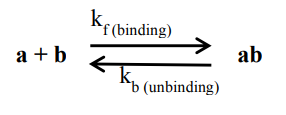

*a. Construct a Petri net that models the system then derive the stoichiometry matrix and the differential equations which model this system (as described in M 1.2 Section 1.2 and M1.4 Section 2)*

Comments: This is a visualization of the petri net for the above reaction: 

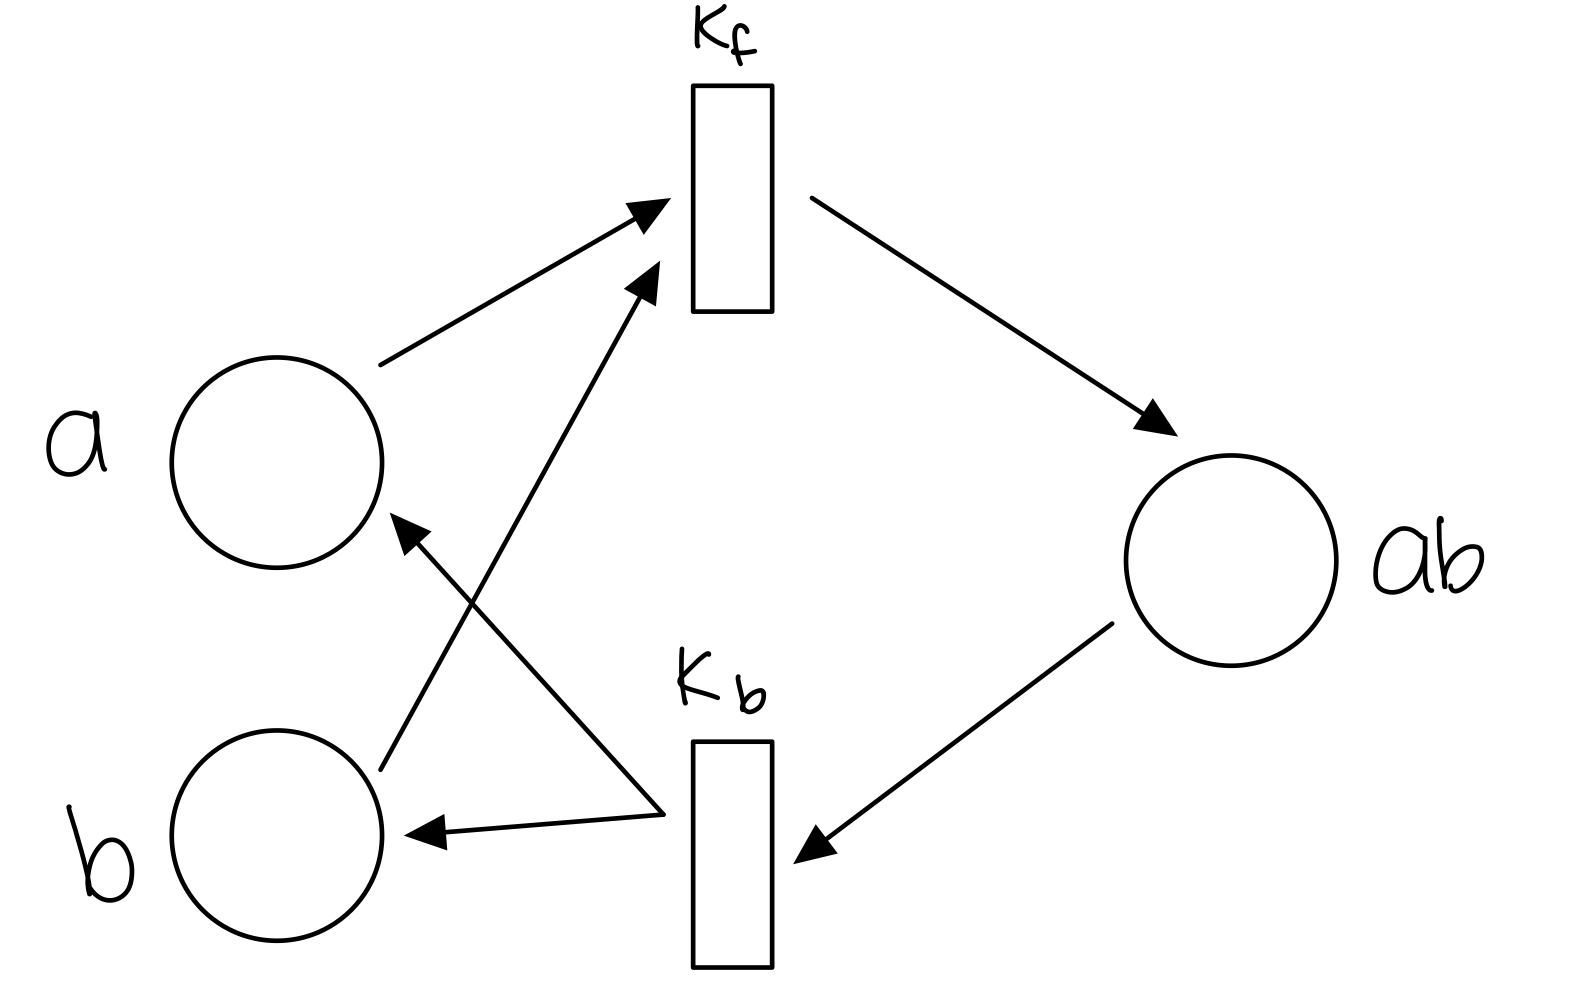

*b. Set up code to simulate the system in MATLAB using the ode45 solver and check it behaves as expected. *

*c. Start the simulation with the reactants in their unbound states i.e. [ab]=0. Explore how adjusting the initial conditions and parameters of the system effect the ratio of unbound a to bound a when the system reaches a steady state. Optionally you can also attempt to do this analytically. *

% answer

%a)
%deriving the stoichiometry matrix
W_sr = [ 1 1 0; 0 0 1]

W_sr =      1     1     0
     0     0     1


W_rs = [ 0 0 1; 1 1 0]

W_rs =      0     0     1
     1     1     0


A = W_rs - W_sr

A =     -1    -1     1
     1     1    -1


%Stoichiometry matrix
S = A'

S =     -1     1
    -1     1
     1    -1


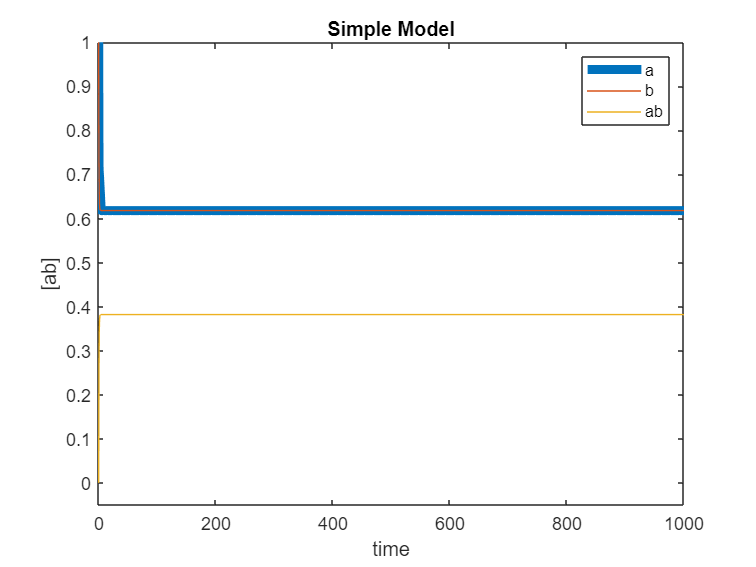


%the differential equations for the simple lac operon model were derived in
%the following way and placed at the function at the bottom of this
%document:
%a + b --kf--> ab
%ab --kb--> a + b
%rate1 = kf*[a]*[b]
%rate2 = kb*[ab]
%x(1) = concentration of a
%x(2) = concentration of b
%x(3) = concentration of ab
%dxdt(1) = kb*x(3) - kf*x(1)*x(2)
%dxdt(2) = kb*x(3) - kf*x(1)*x(2)
%dxdt(3) = kf*x(1)*x(2) - kb*x(3)

%b)
%Hint. For example you	could check that with parameters kf = kb = 1, and	initial	
%conditions	[a]	= 1, [b] = 1, [ab] = 0,	the	system	reaches	a steady state such	that	
%[a] + [ab] = 1	so	that the total amount of reactant a is conserved.

options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 1 0];
% Parameters
kf = 1;
kb = 1;
p = [kf kb];
% Simulation
[t1,x1]=ode45(@model_lac1,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
%the line width of a was increased to 5 as the concentration of a and b
%overlap and could not be distinguished on the plot 
p1(1).LineWidth = 5;
xlabel('time');
ylabel('[ab]');
ylim([-0.05,1]);
xlim([-1,1000])
title('Simple Model')
legend('a', 'b', 'ab')
hold off

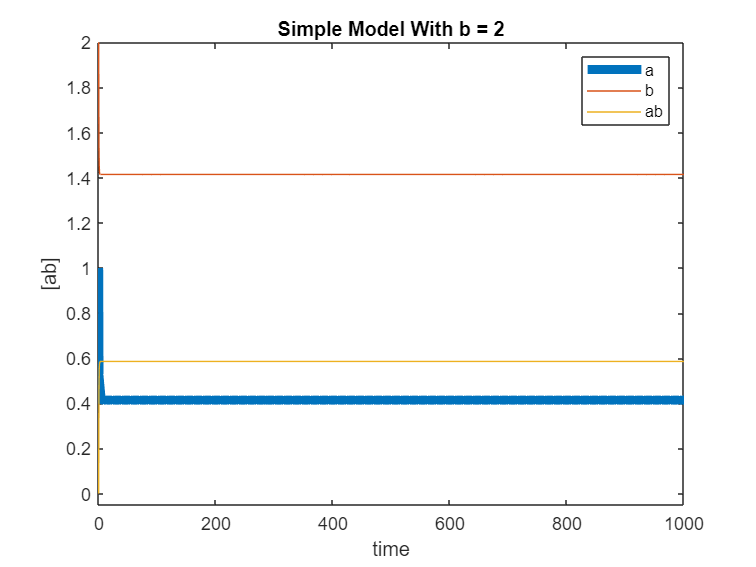

%c)
%Hint.	For	example	explore	the effect	of:	
%i)	changing	the	concentration	of	b		
%ii)	changing	kf and	kb.

%i)changing the concentration of b
%b = 2
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 2 0];
% Parameters
kf = 1;
kb = 1;
p = [kf kb];
% Simulation
[t1,x1]=ode45(@model_lac1,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
%the line width of a was increased to 5 as the concentration of a and b
%overlap and could not be distinguished on the plot 
p1(1).LineWidth = 5;
xlabel('time');
ylabel('[ab]');
ylim([-0.05,2]);
xlim([-1,1000])
title('Simple Model With b = 2')
legend('a', 'b', 'ab')
hold off

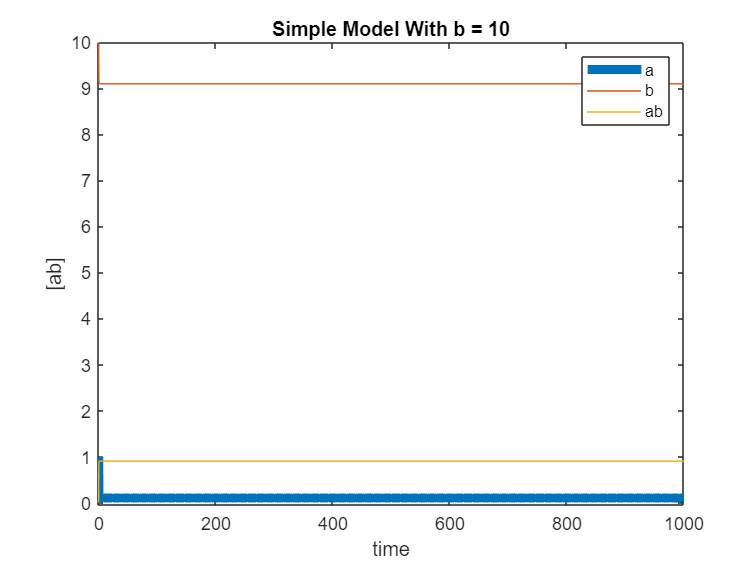

%b = 10 
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 10 0];
% Parameters
kf = 1;
kb = 1;
p = [kf kb];
% Simulation
[t1,x1]=ode45(@model_lac1,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
%the line width of a was increased to 5 as the concentration of a and b
%overlap and could not be distinguished on the plot 
p1(1).LineWidth = 5;
xlabel('time');
ylabel('[ab]');
ylim([-0.05,10]);
xlim([-1,1000])
title('Simple Model With b = 10')
legend('a', 'b', 'ab')
hold off

As expected, increasing the concentration of b changes the the ratio of unbound to bound a when the steady state is reached. As the concentration of b is increased, more of a is bound in the steady state. The higher concentration of b pushes the reaction forward towards the product, ab, meaning there will be less unbound a. 

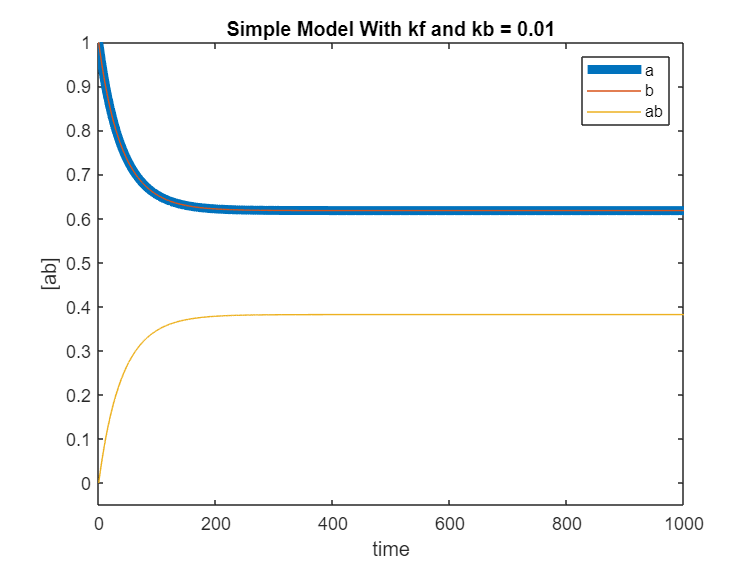

%ii)changing the values of kf and kb
%kf and kb = 0.01
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 1 0];
% Parameters
kf = 0.01;
kb = 0.01;
p = [kf kb];
% Simulation
[t1,x1]=ode45(@model_lac1,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
%the line width of a was increased to 5 as the concentration of a and b
%overlap and could not be distinguished on the plot 
p1(1).LineWidth = 5;
xlabel('time');
ylabel('[ab]');
ylim([-0.05,1]);
xlim([-1,1000])
title('Simple Model With kf and kb = 0.01')
legend('a', 'b', 'ab')
hold off

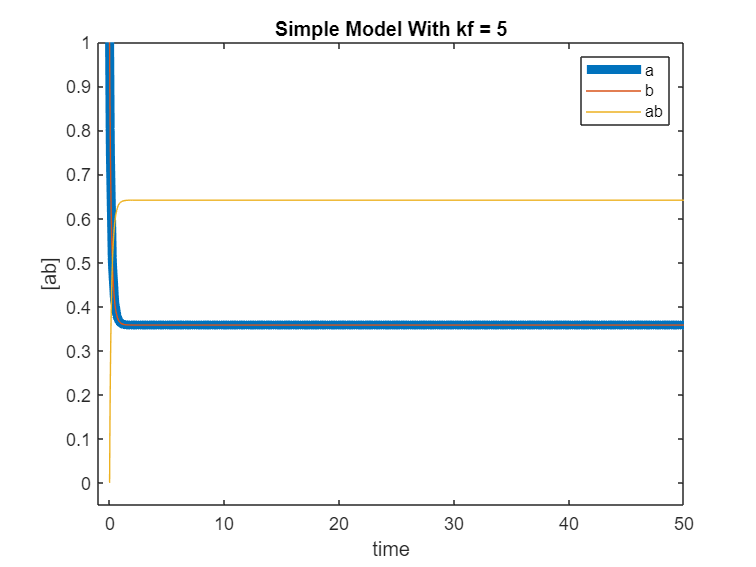


%Note that for the following graphs, the x limit has been decreased to 50 because
%the steady state is reached much faster when the reaction 
%rates are increased that it is impossible to see 
%the curve of the concentrations of everything when zoomed out

%kf = 5
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 1 0];
% Parameters
kf = 5;
kb = 1;
p = [kf kb];
% Simulation
[t1,x1]=ode45(@model_lac1,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
%the line width of a was increased to 5 as the concentration of a and b
%overlap and could not be distinguished on the plot 
p1(1).LineWidth = 5;
xlabel('time');
ylabel('[ab]');
ylim([-0.05,1]);
xlim([-1,50])
title('Simple Model With kf = 5')
legend('a', 'b', 'ab')
hold off

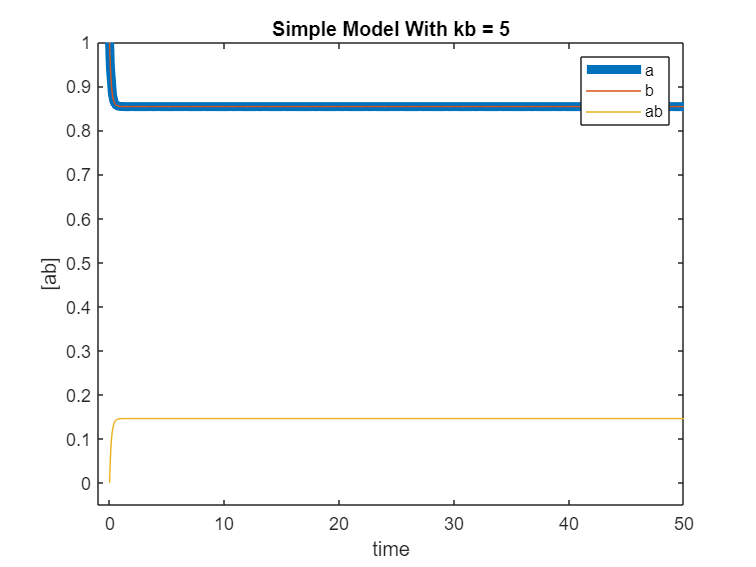

%kb = 5
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 1 0];
% Parameters
kf = 1;
kb = 5;
p = [kf kb];
% Simulation
[t1,x1]=ode45(@model_lac1,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
%the line width of a was increased to 5 as the concentration of a and b
%overlap and could not be distinguished on the plot 
p1(1).LineWidth = 5;
xlabel('time');
ylabel('[ab]');
ylim([-0.05,1]);
xlim([-1,50])
title('Simple Model With kb = 5')
legend('a', 'b', 'ab')
hold off

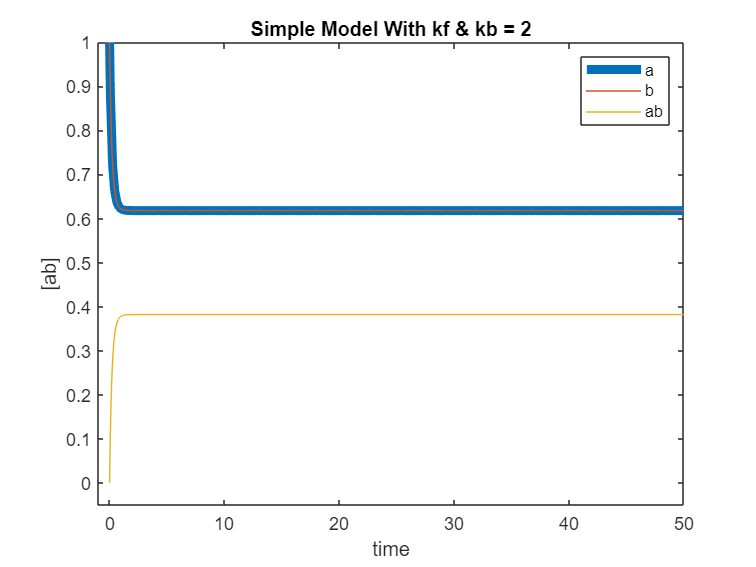

%kb and kf = 2
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 1 0];
% Parameters
kf = 2;
kb = 2;
p = [kf kb];
% Simulation
[t1,x1]=ode45(@model_lac1,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
%the line width of a was increased to 5 as the concentration of a and b
%overlap and could not be distinguished on the plot 
p1(1).LineWidth = 5;
xlabel('time');
ylabel('[ab]');
ylim([-0.05,1]);
xlim([-1,50])
title('Simple Model With kf & kb = 2')
legend('a', 'b', 'ab')
hold off

If the values of kf and kb are decreased, it takes longer for the steady state to be reached as expected. Similarly, when the values of kf and kb are increased, the steady state is reached much faster. When the reaction rate of kf is greater than kb, the steady state is characterized by a higher concentration of ab compared to a alone. This is expected as the reaction of a and b binding to form ab is faster than the reverse reaction. The opposite is true when the value of kb is greater than kf: the steady state is characterized by a higher concentration of a compared to ab because the breakdown of ab happens faster than the binding of a and b. 

## Suggested Step 2

The lac operon can be built by combining two such reversible binding reactions. These involve gop, LacI, alac, and their bound forms LacI-gop and LacI-alac. 

*a. Write down the four reactions that occur and use these to derive the stoichiometry matrix that describes the system*

*b. Use this to generate the differential equations that encode the model. You can leave the reaction rates as unknown parameters k1, k2, k3, and k4.  *

*c. Using understanding of biology/common sense/literature comment on the relative abundance of the five species when the operon is inhibited / active. *

*d. Use you results of exploring reaction a + b *⇄ *or otherwise, and try to explain how the values of k1, k2, k3, and k4 must be set in order to reproduce the regulatory behavaiour. *

*e. Set up code to simulate the system in MATLAB using the ode45 solver. Test your code behaves as expected. *

*f. Explore how the model can be used to demonstrate the mechanism of the Lac operon to change from an inhibited state when alac is absent to an active state when alac is present. *

*g. Now demonstrate that if you repeat the simulation keeping the same parameter values and initial conditions, except in the presence of alac, the modelled system then reaches a different steady state in which a fraction of gop is unbound and therefore free to express. *

%answer 
%a) 
% Define the input matrix
W_sr = [1 1 0 0;     0 0 1 1];

% Define the output matrix
W_rs = [0 0 1 0;     0 0 0 1];

A = W_rs - W_sr

A =     -1    -1     1     0
     0     0    -1     0



%Stoichiometry matrix 
S = A'

S =     -1     0
    -1     0
     1    -1
     0     0



%b)
%rate1_forward = k1 * gop * lacI; % forward rate equation for lacI binding gop
%rate1_reverse = k2 * gop-lacI; % reverse rate equation 
%rate2_forward = k3 * lacI * alac; % forward rate equation for alac binding lacI
%rate2_reverse = k4 * lacI-alac; % reverse rate equation 

%x(1) = concentration of gop
%x(2) = concentration of lacI
%x(3) = concentration of gop-lacI
%x(4) = concentration of alac
%x(5) = concentration of lacI-alac

%dxdt(1) = k2*x(3) - k1*x(1)*x(2) 
%dxdt(2) = k2*x(3) + k4*x(5) - k1*x(1)*x(2) - k3*x(2)*x(4)
%dxdt(3) = k1*x(1)*x(2) - k2*x(3)
%dxdt(4) = k4*x(5) - k3*x(2)*x(4)
%dxdt(5) = k3*x(2)*x(4) - k4*x(5)
%these differential equations have been put in the function below

%c)

I will be using common sense and biological knowledge rather than literature to comment on the relative abundance of the species involved in this model. 

When the operon is inhibited: 

The relative abundance of gop will be near 0 as lacI will be bound to gop to prevent transcription and translation of the genes to breakdown lactose. However, it will not be 0 as some expression always occurs. The relative abundance of lacI will also be near 0 as all lacI should be bound to gop rather than free in solution. Following the same logic, gop-lacI will be abundant. Alac and lacI-alac will have relative abundance of 0 as no allolactose is present in the inhibited state. 

When the operon is active: 

The relative abundance of gop will be high as it is no longer inhibited by lacI. The relative abundance of free lacI will still be low as now it will be bound to alac rather than gop. The relative abundance of gop-lacI will be low for the same reason. Alac will be somewhat abundant, and lacI-alac will be highly abundant as alac will bind to lacI. 

%d)

Based on biological knowledge, the values of the rate constants have been arbitrarily selected. When only lacI is present, it is known that nearly all of gop will be in its bound form. Therefore, the rate constant for k1, i.e. the formation of gop-lacI, must be much greater than the rate constant for the degradation of gop-lacI. So k1 was set at 1.5 and k2 at 0.1. Since alac is capable of binding lacI and causing it to release gop, k3 must be much greater than k1. Therefore, k3 was set to be 10x faster than k1 and k4 was set to a low value as alac should not release lacI until the lactose breakdown enzymes have been expressed and can process the alac in the cell. 

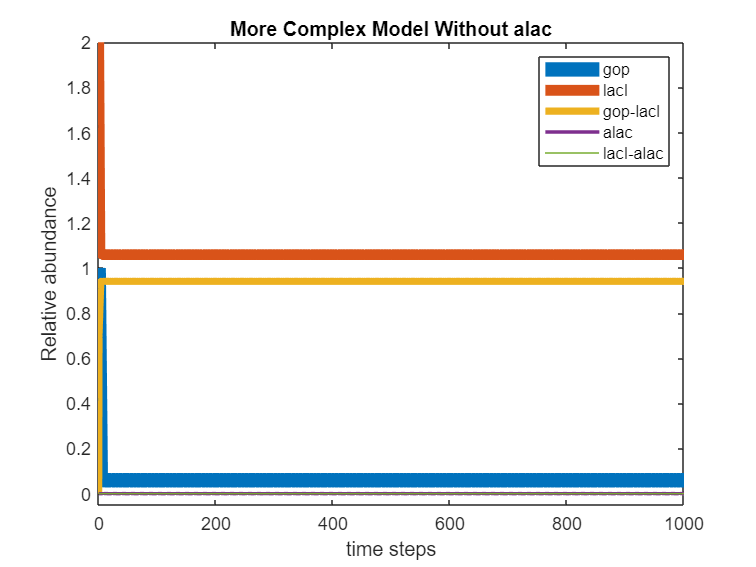

%e)
%alac is absent
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 2 0 0 0];
% Parameters
k1 = 1.5;
k2 = 0.1;
k3 = 15;
k4 = 0.2;
p = [k1 k2 k3 k4];
% Simulation
[t1,x1]=ode45(@model_lac2,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
p1(1).LineWidth = 8;
p1(2).LineWidth = 6;
p1(3).LineWidth = 4;
p1(4).LineWidth = 2;
xlabel('time steps');
ylabel('Relative abundance');
ylim([-0.05,2]);
xlim([-1,1000])
title('More Complex Model Without alac')
legend('gop', 'lacI', 'gop-lacI', 'alac', 'lacI-alac')
hold off

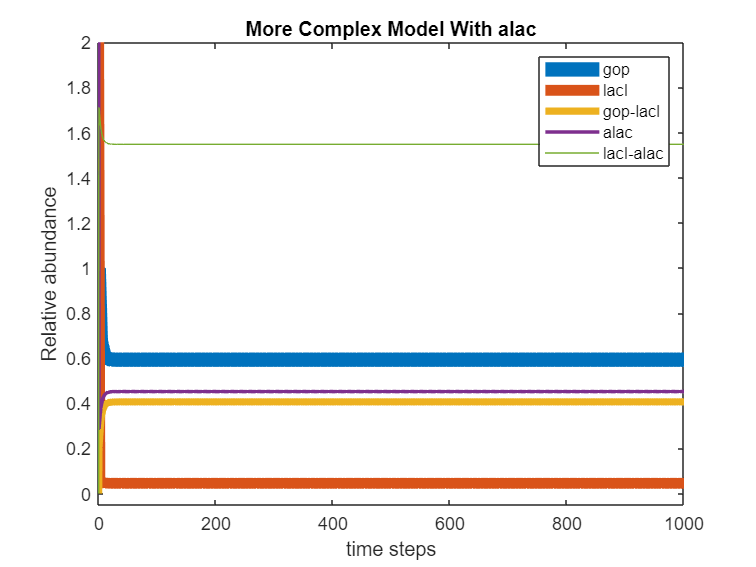

%alac is present 
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 2 0 2 0];
% Parameters
k1 = 1.5;
k2 = 0.1;
k3 = 15;
k4 = 0.2;
p = [k1 k2 k3 k4];
% Simulation
[t1,x1]=ode45(@model_lac2,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
p1(1).LineWidth = 8;
p1(2).LineWidth = 6;
p1(3).LineWidth = 4;
p1(4).LineWidth = 2;
xlabel('time steps');
ylabel('Relative abundance');
ylim([-0.05,2]);
xlim([-1,1000])
title('More Complex Model With alac')
legend('gop', 'lacI', 'gop-lacI', 'alac', 'lacI-alac')
hold off

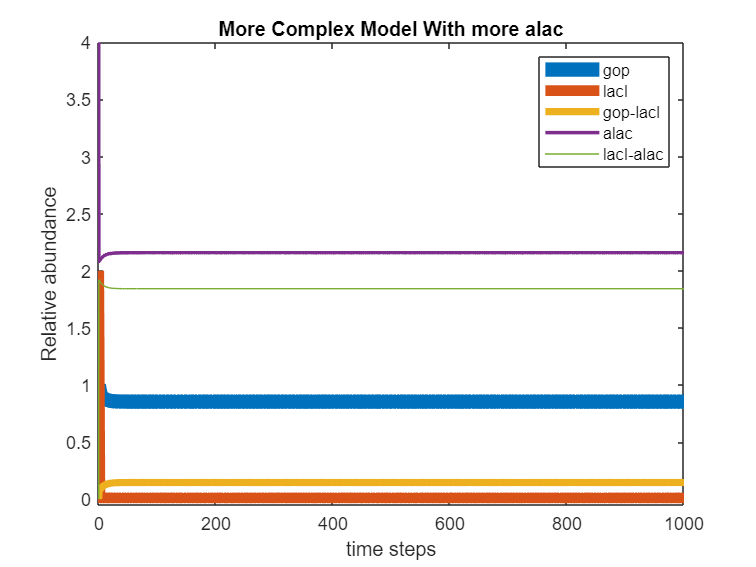

%more alac is added
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range = [0 1000];
x_ini   = [1 2 0 4 0];
% Parameters
k1 = 1.5;
k2 = 0.1;
k3 = 15;
k4 = 0.2;
p = [k1 k2 k3 k4];
% Simulation
[t1,x1]=ode45(@model_lac2,t_range,x_ini,options,p);
 
% Plot time series of ab
p1 = plot(t1,x1(:,:));
p1(1).LineWidth = 8;
p1(2).LineWidth = 6;
p1(3).LineWidth = 4;
p1(4).LineWidth = 2;
xlabel('time steps');
ylabel('Relative abundance');
ylim([-0.05,4]);
xlim([-1,1000])
title('More Complex Model With more alac')
legend('gop', 'lacI', 'gop-lacI', 'alac', 'lacI-alac')
hold off

As can be seen from the plots, the model accurately reflects the behavior of the lac operon. When alac is absent, nearly all of gop is bound by lacI, so it is repressed and the lactose processing enzymes cannot be expressed. When alac is present, a fraction of gop becomes free so that transcription proteins can bind and express the enzymes. If additional alac is present, more of gop will in the free form as more enzymes need to be expressed to process the amount of alac present. 

***Local functions:***

*(these are always placed together in single section at the end of the Live Script file) *

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1 Original reversible reaction model 


function dxdt=model_lac1(t,x,p)
% Initialize model vector with zeroes,
dxdt=zeros(3,1);
% Parameters
kf=p(1);  %     rate of a + b binding 
kb=p(2);  %     rate of ab degrading to a + b

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Differential Equation:
%
% unbound a and b
dxdt(1) = kb*x(3) - kf*x(1)*x(2);
dxdt(2) = kb*x(3) - kf*x(1)*x(2);
% bound ab
dxdt(3) = kf*x(1)*x(2) - kb*x(3);
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%
%more complex lac operon model 
function dxdt=model_lac2(t,x,p)
% Initialize model vector with zeroes,
dxdt=zeros(5,1);
% Parameters
k1=p(1);  %     rate of lacI binding gop
k2=p(2);  %     rate of lacI-gop release
k3=p(3);  %     rate of alac binding lacI
k4=p(4);  %     rate of lacI-alac release

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Differential Equation:
%
dxdt(1) = k2*x(3) - k1*x(1)*x(2);  %gop
dxdt(2) = k2*x(3) + k4*x(5) - k1*x(1)*x(2) - k3*x(2)*x(4); %lacI
dxdt(3) = k1*x(1)*x(2) - k2*x(3); %gop-lacI
dxdt(4) = k4*x(5) - k3*x(2)*x(4); %alac
dxdt(5) = k3*x(2)*x(4) - k4*x(5); %lacI-alac
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%
end
